# Guiao 7

## 7.1


% 
% % user ID | movie ID | rating | timestamp
% 
% % C´odigo base para deteçao de pares similares
% udata=load('ml-100k/u.data'); % Carrega o ficheiro dos dados dos filmes
% 
% % Fica apenas com as duas primeiras colunas
% u= udata(1:end,1:2); clear udata;
% 
% % Lista de utilizadores
% users = unique(u(:,1)); % Extrai os IDs dos utilizadores
% 
% Nu= length(users); % Numero de utilizadores
% fprintf("Numero de utilizadores: %d \n",Nu)
% 
% % Constr´oi a lista de filmes para cada utilizador
% Set= cell(Nu,1); % Usa celulas
% 
% for n = 1:Nu % Para cada utilizador
%     % Obt´em os filmes de cada um
%     ind = find(u(:,1) == users(n));
%     % E guarda num array. Usa celulas porque utilizador tem um numero
%     % diferente de filmes. Se fossem iguais podia ser um array
%     Set{n} = [Set{n} u(ind,2)];
% end
% 
% %% Calcula a distancia de Jaccard entre todos os pares pela definicao.
% J=zeros(Nu); % array para guardar distˆancias
% 
% h= waitbar(0,'Calculating');
% 
% for n1= 1:Nu
%     waitbar(n1/Nu,h);
%     for n2= n1+1:Nu
%         %% Adicionar c´odigo aqui
% 
%         C1 = Set{n1};
%         C2 = Set{n2};
%         intersecao = intersect(C1,C2);
%         uniao = union(C1,C2);
%         similJ = length(intersecao) / length(uniao);
%         distJ = 1- similJ;
%         J(n1,n2) = distJ;
% 
%     end
% end
% 
% delete (h)
% 
% %% Com base na distancia, determina pares com
% %% distancia inferior a um limiar pre-definido
% threshold =0.4 % limiar de decisao
% 
% % Array para guardar pares similares (user1, user2, distancia)
% SimilarUsers= zeros(1,3);
% k= 1;
% 
% for n1= 1:Nu
%     for n2= n1+1:Nu
%         if J(n1,n2) < threshold
%          SimilarUsers(k,:)= [users(n1) users(n2) J(n1,n2)]
%          k= k+1;
%         end
%     end
% end


## passo 1 - criar conjuntos

[Set,Nu,users] = criar_conjuntos('ml-100k/u.data');

## passo 2 - calcular distancia

J = calcular_distancia(Set, Nu);
save J.mat J -mat

## passo 3 - calcular pares similares

threshold = .4;
SimilarUsers = calcular_pares_similares(J,Nu, users, threshold);
SimilarUsers

SimilarUsers =   328.0000  788.0000    0.3270
  408.0000  898.0000    0.1613
  489.0000  587.0000    0.3701


## 4

## hash test



k = 10;
R.a = randi(123457,1,k);
R.b = randi(123457,1,k);
R.p = 123457;
elem = 123;

for hf = 1: 10
    hc = hash_function(elem,hf,R);
    fprintf("%d -> %d\n",elem, hc)
end

123 -> 40759
123 -> 30403
123 -> 63992
123 -> 48882
123 -> 92452
123 -> 35590
123 -> 87011
123 -> 22091
123 -> 99635
123 -> 22177


## passo 1 - criar conjuntos

% [Set,Nu,users] = criar_conjuntos('ml-100k/u.data');

## passo 2 - calcular distancia

% k = 10
% J = calcular_distancia_minhash(Set,Nu,k);
% save J_MH.mat J -mat

## passo 3 - calcular pares similares

% threshold = .4;
% SimilarUsers = calcular_pares_similares(J,Nu, users, threshold);
% SimilarUsers


## 7.2

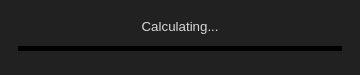

ks = 3;
Shingles = getShingles("film_info.txt", ks);

p = 1234567;

while ~isprime(p)
    p = p + 2;
end

nhf = 200;
R = randi(p, nhf, ks);
MA = minhash_2(Shingles, nhf, R, p);  % MinHash matrix for original shingles

testShingles = getShingles("a.txt", ks);
MA2 = minhash_2(testShingles, nhf, R, p);  % MinHash matrix for test shingles

% Number of columns in MA and MA2 (Nu - number of sets)
Nu = size(MA, 2);  % Assuming both matrices have the same number of columns

% Initialize the distance matrix J
J = zeros(Nu);

% Waitbar for progress tracking
h = waitbar(0, 'Calculating...');


% Calculate Jaccard similarity between each pair of columns from MA and MA2
for n1 = 1:Nu
    for n2 = n1+1:Nu
        % Get the MinHash signatures for the two sets
        assinatura1 = MA(:, n1);
        assinatura2 = MA2(:, n2);
        
        % Count the number of matching hash values (Jaccard similarity approximation)
        vi = sum(assinatura1 == assinatura2);  % Number of matching hash values
        
        % Similarity = Number of matching values / k (number of hash functions)
        similarity = vi / nhf;  % This is the MinHash approximation of Jaccard similarity
        J(n1, n2) = similarity;  % Store the similarity in the matrix
        J(n2, n1) = similarity;  % Symmetric matrix (similarity(n1, n2) = similarity(n2, n1))
    end
    % Update the waitbar progress
    waitbar(n1 / Nu, h);
end

Index in position 2 exceeds array bounds. Index must not exceed 2.


% Close the waitbar
close(h);

% Display the similarity matrix
disp(J);
